# Module 5, Lesson 1: Summary statistics as features

This reading demonstrates the topics and examples from the video "Summary Statistics as Features".

## Load the data

In the file `AccelerometerData.mat`, there are two timetables. They each contain recordings from a smartphone accelerometer while doing different activities. The types of activities are identified in the variable names:

- `StandWalk` - standing, then walking

- `WalkStairs` - walking normally, then walking up stairs.

load AccelerometerData.mat StandWalk WalkStairs

To start, visualize the variable `StandWalk`. You can plot all the channels at once with the function `stackedplot`

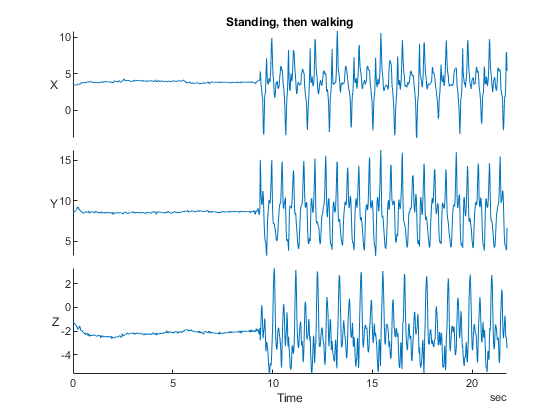

stackedplot(StandWalk);
title("Standing, then walking")

## Applying summary statistics to entire signals

#### Signals in separate variables

If your data is separated into different signals, then you can use summary statistic functions like `mean` and `std`. For example, you could separate out a walking and standing signal based on the time that the activity changed.

Here, the signal from the Y channel of `StandWalk` is split into two pieces. Then, the mean and standard deviation are calculated for each.

% Extract the two signals assuming the activity changes at 9.3 seconds
standSignal = StandWalk.Y(StandWalk.Time < seconds(9.3));
walkSignal = StandWalk.Y(StandWalk.Time >= seconds(9.3));

% Calculate stats
mean(standSignal)

ans = 8.6224

mean(walkSignal)

ans = 8.5864

std(standSignal)

ans = 0.1162

std(walkSignal)

ans = 2.7927

You can see the mean values are very similar, but there's a larger difference in the standard deviation.

## Applying summary statistics to windows

In practice, you probably won't know the exact time that a signal changes. Instead, you can split a signal up into a series of "windows" and apply a summary statistic to each window. This will give you a sense of how the signal changes over time. 

An important consideration is how long to make the window. It should be long enough that the summary statistic is a valid estimation of the distribution of values, but short enough to be able to measure changes in the signal over time.

Use the controls below to try applying some different sized windows and summary statistics to the `StandWalk` table

windowLength = 2.5;
summaryStat = "mean";
summaryStandWalk = retime(StandWalk,"regular",summaryStat,"TimeStep",seconds(windowLength));

The output from `retime` is another timetable but with average values. You can plot these values to see how the statistic changes over time.

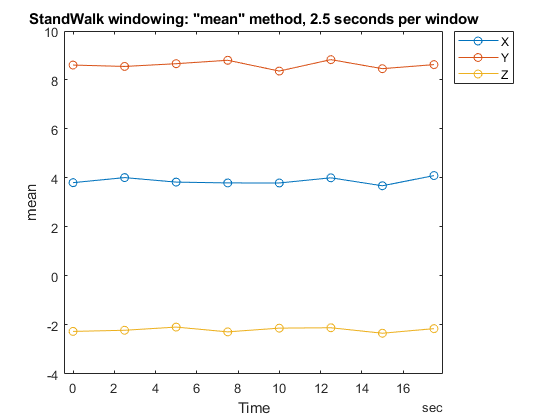

% Plot the result from all channels
plot(summaryStandWalk.Time(1:end-1),summaryStandWalk{1:end-1,["X","Y","Z"]},'o-')
xlabel("Time")
ylabel(summaryStat)
legend(["X","Y","Z"],"Location","BestOutside")
title(compose("StandWalk windowing: ""%s"" method, %.1f seconds per window", ...
    summaryStat,windowLength));

The mean value does not change much, but other statistics like min and max show a change over time.

Note that the last entry in this table is not plotted. This is because the last data point is calculated with however much data was left over after the last full window. In other words, for a window length of 5 seconds, the full windows are from 0 - 5 seconds, 5 - 10 seconds, 10 - 15 seconds, and 15 - 20 seconds. Since the last time point is at 21.74 seconds, then the last window is only from 20 - 21.74 seconds. This window is much smaller, so you may want to remove this data point if you only want to consider full windows.

## Windowing with standard deviation

Now repeat the same process with the standard deviation. This statistic is not one of the default options for retime, but you can refer to any function with an "@" symbol. So instead of a string like `"std"`, you write `@std` (without quotation marks). 

Try using different window lengths and see the effect on the standard deviation.

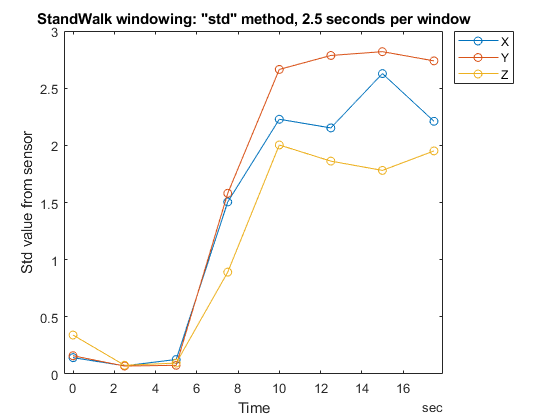

% Apply windowing
windowLength = 2.5;
stdStandWalk = retime(StandWalk,"regular",@std,"TimeStep",seconds(windowLength));

% Make plot
plot(stdStandWalk.Time(1:end-1),stdStandWalk{1:end-1,["X","Y","Z"]},'o-')
xlabel("Time")
ylabel("Std value from sensor")
legend(["X","Y","Z"],"Location","BestOutside")
title(compose("StandWalk windowing: ""std"" method, %.1f seconds per window",windowLength))

Notice the standard deviation values changes significantly in all three channels over time. Therefore, the standard deviation might be a good feature to use for discriminating between standing and walking behaviors.

## Plotting the frequency spectrum

Next, take a look at the W`alkStairs` data, which is from a person walking normally for 30 seconds, followed by 30 seconds of walking up stairs.

There is a visible change in the signal at 30 seconds, but the overall amount of activity is similar. Summary statistics like mean and standard deviation would do a poor job of describing these differences

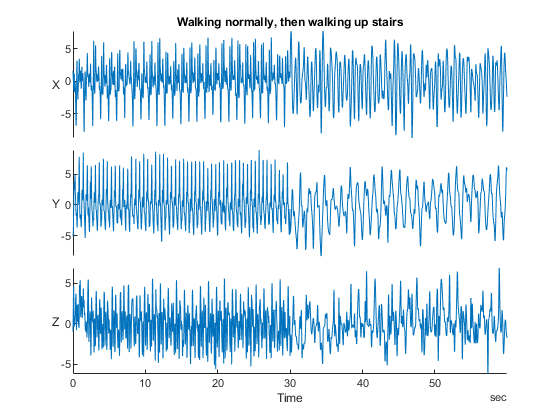

stackedplot(WalkStairs);
title("Walking normally, then walking up stairs")

Note that these signals have been "de-trended", meaning any offsets were subtracted off so that each signal is centered at zero. This isn't necessary, but it makes the visualization nicer. If you want to see the effect, try adding an offset to the signal before calculating the spectrum below.

#### Spectrum plot

To visualize the frequency content of signals, plot the frequency spectrum. The first function you'll use is `periodogram`, which calculates a "power spectral density". A full explanation of this function is beyond the scope of this course, but essentially, the Fourier transform of the signal is calculated, and then the values are squared and normalized to get units of "Power/Hz". The term "power" is a holdover from electrical engineers, since they tend to report their spectra in units of actual electric power (watts). The term "density" is used because the values are reported "per Hz".

You can make a plot by calling periodogram with no output. Here's an example for just the "walking normally" signal.

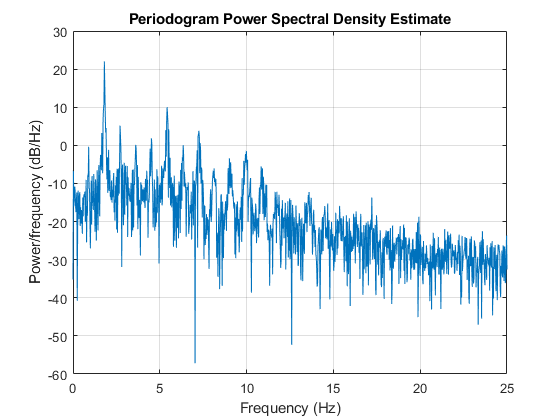

% Extract the "walking normally" signal from one channel
walkSignal = WalkStairs.Y(WalkStairs.Time < seconds(30));

% Get the sample rate from the timetable
sampleRate = WalkStairs.Properties.SampleRate;

% Plot the periodogram. The empty inputs [] specify that the default values
% should be used.
periodogram(walkSignal,[],[],sampleRate);

Notice the units reported as "dB/Hz". The dB stands for decibel, which is a log transformation. Specifically, if the periodogram returns a variable $P$, then the value in dB is: $P_{\textrm{dB}} 10\cdot \log_{10} \left(P\right)$.

## Spectral centroid example

The **spectral centroid** is a weighted average of the frequency values in the spectrum. It's a measure of where the "center" of the spectrum is, similar to how the mean is the "center" of a statistical distribution.

You can calculate the centroid with the function `spectralCentroid`. This function will split up a signal into 30 ms long windows by default and return a centroid value for each window. However, you can specify a `"Window"` option to set your own window length. The code below specifies that the entire signal should be used to calculate a single number.

In the field of signal processing, [there are many different types of windows](https://www.mathworks.com/help/signal/ug/windows.html). A full discussion of windowing is beyond the scope of this course, but below we use a "rectangular" window that treats each point in the window equally. Other types of windows include a taper at the beginning and end of the signal, but they're not necessary for this demonstration.

% Create a window that's the same length of the signal, but all ones.
% In signal processing, this is referred to a "rectangular" window
window = rectwin(length(walkSignal));

% Calculate the spectral centroid
walkCentroid = spectralCentroid(walkSignal,sampleRate,"Window",window)

walkCentroid = 2.8864

You can now compare this value for the walking up stairs signal. The value is lower because this signal has less energy at higher frequencies.

% Calculate a spectral centroid for a stairs signal
stairSignal = WalkStairs.Y(WalkStairs.Time >= seconds(30));
window = rectwin(length(stairSignal));
stairCentroid = spectralCentroid(stairSignal,sampleRate,"Window",window)

stairCentroid = 1.1085

## Applying spectral statistics with windows 

Finally, you can bring together everything in this script to calculate spectral statistics over time using windowing. These functions have built-in windowing functionality, so you don't need to use `retime`. Remember that the activity switches from walking normally to walking up stairs at around 30 seconds.

First, pick out a channel, window length, and summary statistic

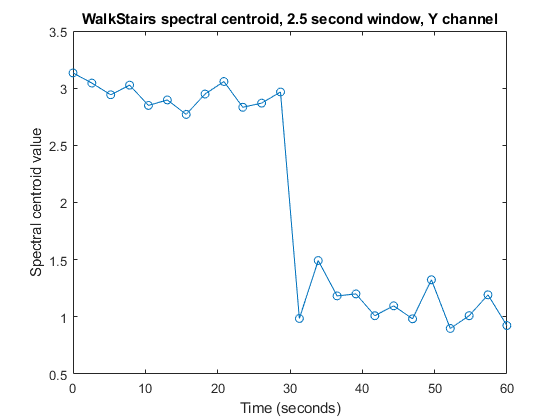

% Choose a channel and extract that signal from the table
channel = "Y";
signal = WalkStairs.(channel);

% Choose a window length for the summary stat calculation
windowLength = 2.5;
window = rectwin(windowLength*sampleRate);

% Calculate the spectral summary statistic
statValues = spectralCentroid(signal,sampleRate,"Window",window);

% Get a time vector based on the number of summary stat values
timeValues = linspace(0,length(signal)/sampleRate,length(statValues));

% Create the plot
plot(timeValues,statValues,'o-')
xlabel("Time (seconds)")
ylabel("Spectral centroid value")
title(compose("WalkStairs spectral centroid, %.1f second window, %s channel", ...
    windowLength,channel))

Notice that the spectral centroid is higher at the beginning and then drops when the activity changes. Therefore, this could be a useful feature for discriminating these two activities. 

Beside the spectral centroid, there are a number of different summary spectral statistics that could be used. These include:

- Spectral spread

- Spectral skewness

- Spectral kurtosis

- Spectral entropy

- Spectral slope

- Spectral flux

For a description of all the options for spectral summary statistics, [check out the documentation](https://www.mathworks.com/help/audio/ug/spectral-descriptors.html). 